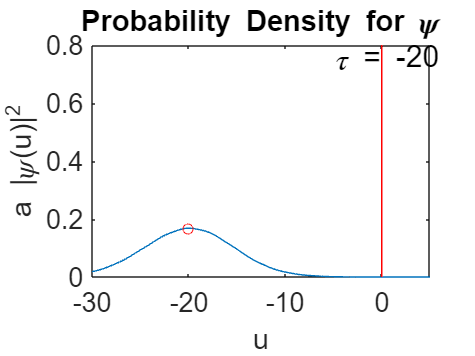

% Set constants
beta=4;
K0=1;
tau=-20;

% Define a range to compute |psi|^2 over
uvals=-30:0.025:5;

% Compute |psi|^2 at each u
psisquared = getpsisquared(uvals, tau, beta, K0);

% Plot |psi|^2
p=plot(uvals, psisquared);
p.Parent.FontSize = 16;
title('Probability Density for \psi');
xlabel('u');
ylabel('a |\psi(u)|^2');
axis([-30,5,0,0.8]);
text(-5, 0.75, ['\tau = ',num2str(tau)],'FontSize',18);
line([0 0], [0 0.8], 'Color', [1 0 0]); % Add in a line at the step

% Compute where the maxima of |psi|^2 is located
[~, loc] = max(psisquared);
hold on
plot(uvals(loc), psisquared(loc), 'ro')
hold off

disp(['Location of maximum: u = ',num2str(uvals(loc))])

Location of maximum: u = -19.975



% Function to compute |psi|^2

function psisquared = getpsisquared(uvals, tau, beta, K0)
    % Initialize a vector of psisquared for u positions
    psisquared=zeros(1,length(uvals));

    % Define a function to integrate
    % x <= 0
    func = @(k, u, t) exp(-beta^2*(k-K0).^2).*exp(-1i*k.^2*t/2).*(exp(1i*k*u)-exp(-1i*k*u).*(1-k.^2+1i*k.*sqrt(2-k.^2)));
    % x > 0
    func2 = @(k, u, t) exp(-beta^2*(k-K0).^2).*exp(-1i*k.^2*t/2).*exp(-sqrt(2-k.^2)*u).*(2*k)./(k+1i.*sqrt(2-k.^2));

    % Iterate over all u positions
    for i = 1:length(uvals)
        u = uvals(i);
        % Integrate to obtain the value of the wavefunction at that u
        if u <= 0
            psi = integral(@(k) func(k, u, tau), 0, sqrt(2));
        else
            psi = integral(@(k) func2(k, u, tau), 0, sqrt(2));
        end
        % Store psi^2
        psisquared(i) = abs(psi)^2;
    end
end
